# Multivariate scattered interpolation (1)

*© *Copyright 2022 The MathWorks, Inc

## Quasi-random (low discrepancy) Halton dataset

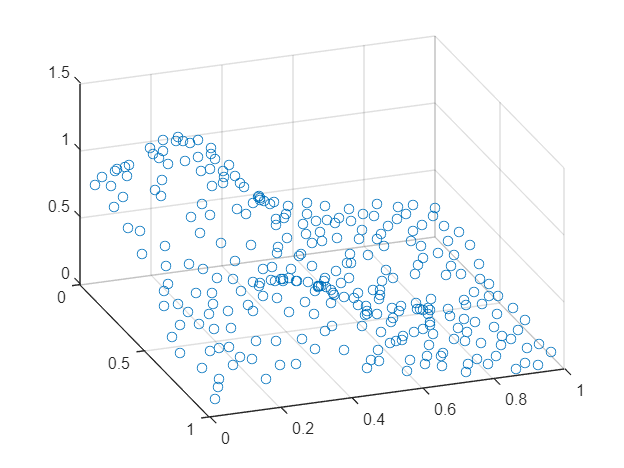

d = 2;                                              % d = space dimension
N = (2^4+1)^2;                                      % N = number of scattered points in R^d

% Generate quasi - random Halton set (see MATLAB Doc for Skip and Leap properties )
p = haltonset (d,'Skip' ,1e3 ,'Leap' ,1e2 );        % define quasi - random object in d- dim
p = p.scramble ('RR2');                             % use scramble method ( reverse - radix )
X = p.net (N);                                      % use net method to generate N points in R^d
F = franke(X(:,1), X(:,2));                         % compute Franke 's test function

scatter3(X(:,1) ,X(:,2) ,F)
view ([70 35])